#  ECSE 343: Numerical Methods in Engineering

#  Assignment 3

Due Date: 23rd March 2023

Student Name: Chenyi Xu

Student ID:    260948311

Please type your answers and write you code in this .mlx script. If you choose to provide the handwritten answers, please scan your answers and include those in SINGLE pdf file.

Please submit this **.mlx** file along with the **PDF** copy of this file.

Note: Make sure that the you have downloaded the data file named* q1_refSol.mat. *You must store the data file in the smae directory as the Assignment 3 file.

## Question 1:  

You are given the following 3rd order differential equation,

              
$$y^{'''}(t) + 32 y^{''} (t) +61.25 y'(t)  + 37.5 y(t)  = sin(\frac{\pi t} {4})$$


a. Transform the above differential equation into a system of first-order differential equations. **(5 marks)**

*        % Show all your work here. Write all your steps and equations.*

*%New variables*

$x_1$ = y

$x_2$ = y'

$x_3$ = y'' 

% Matrix form


$$\left\lbrack \begin{array}{c}
{x_1 }^{\prime } \\
{x_2 }^{\prime } \\
{x_3 }^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
\sin \left(\frac{\pi t}{4}\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-37\ldotp 5 & -61\ldotp 25 & -32
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack$$


b.  For the system of first order ODEs obtained in part a, apply the Backward Euler approximation for the derivative and write the obtained **difference Equations **below. **(5 marks)**

*        % type your answer here, write all the equations*

Backward sub $\frac{{{\mathit{\mathbf{X}}}_n -\mathit{\mathbf{X}}}_{n-1\;} }{\Delta t}\;=\mathit{\mathbf{M}}\;{\mathit{\mathbf{X}}}_n +{\mathit{\mathbf{B}}}_n$      <=> $\left(\frac{\mathit{\mathbf{I}}}{\Delta t}\;-\mathit{\mathbf{M}}\right)\;\;{\mathit{\mathbf{X}}}_n =\;{\mathit{\mathbf{B}}}_n +\frac{{\mathit{\mathbf{X}}}_{n-1} }{\Delta t}$

where M = $\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-37\ldotp 5 & -61\ldotp 25 & -32
\end{array}\right\rbrack$ ${\mathit{\mathbf{B}}}_n$ =$\left\lbrack \begin{array}{c}
0\\
0\\
\sin \left(\frac{\pi t}{4}\right)
\end{array}\right\rbrack$ $I$ is the 3x3 identiy matrix 

c.  You are provided with the initial conditions, $y(0) =0$, $y'(0) =1$, and  $y''(0) = 0$ for the given differential equation.  Use the cell below to implement the Backward Euler method to solve the first order ODE's obtained in part a . Run the simulation for $25s$, use the time step $\Delta t= 0.065s$.  

Plot  $y(t)$ vs $t$ on the same plot as the true solution, label your plots appropriately. **(5 marks)**

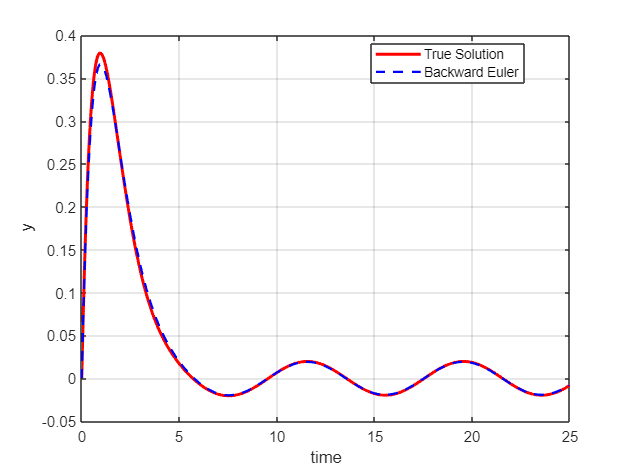


clear all
dT = 0.065; %sec
T = 0:dT:25; 

%-----------------------------------------------------------------------------
% write the your code here.

% Initial Condition
I = eye(3);
x(:, 1) =[0; 1; 0]; 
M = [0 1 0; 0 0 1; -37.5 -61.25 -32];


for n = 2:length(T)
    x(:,n) = inv(I - dT .* M) * (x(:,n-1) + dT .* [0; 0; sin(pi*T(n)/4)]);
end




%------------------------------------------------------------------------------
load('q1_refSol.mat') % load true analytical sol for reference.

figure()
plot(Q1_Tref,Q1_ref_sol,'r-','LineWidth',2,'displayname','True Solution') % plots true solution for comparison
hold on 
%-------------------------------------------------------------------------------


% plot your solution here.
plot(T,x(1,:),'b--','LineWidth',1.5,'displayname','Backward Euler')
% Note: the variable y is the y(t).  You may choose to rename it according
% to your preference,.                                        
%--------------------------------------------------------------------------------                                                              
                                                              
xlabel('time')
ylabel('y')
grid on
legend("Location","best")

d.  Run the code you wrote in part c again, run the code for $25s$ and use the time step $\Delta t= 1s$.  Plot  $y(t)$ vs $t$ on the same plot as the true solution.

 Is the obtained solution more accurate than the solution in part c? Explain.  **(2 marks)**

*Note: You may copy the code you wrote in part c in the cell below to run it for *$\Delta t =1s$ 

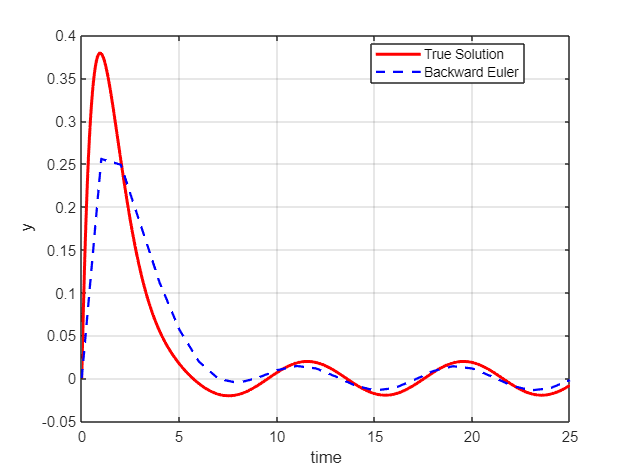


clear all
dT = 1; %sec
T = 0:dT:25; 

%-----------------------------------------------------------------------------
% write the your code here.

% Initial Condition
I = eye(3);
x(:, 1) =[0; 1; 0]; 
M = [0 1 0; 0 0 1; -37.5 -61.25 -32];


for n = 2:length(T)
    x(:,n) = inv(I - dT .* M) * (x(:,n-1) + dT .* [0; 0; sin(pi*T(n)/4)]);
end




%------------------------------------------------------------------------------
load('q1_refSol.mat') % load true analytical sol for reference.

figure()
plot(Q1_Tref,Q1_ref_sol,'r-','LineWidth',2,'displayname','True Solution') % plots true solution for comparison
hold on 
%-------------------------------------------------------------------------------


% plot your solution here.
plot(T,x(1,:),'b--','LineWidth',1.5,'displayname','Backward Euler')
% Note: the variable y is the y(t).  You may choose to rename it according
% to your preference,.                                        
%--------------------------------------------------------------------------------                                                              
                                                              
xlabel('time')
ylabel('y')
grid on
legend("Location","best")

*% type your answer here*

*The obtained solution in part C is more accurate.  *The Backward Euler method is always stable for all values of step sizes. However, the accuracy of the BE method is affected by the step size, $\Delta t$. The smaller the step size, the more accurate the solution will be.

e. For the system of first-order ODEs obtained in part a, use the Forward Euler approximation for the derivative and write the obtained difference Equations below. **(5 marks)**

*        %  type your answer here. Show all the equations and steps.*

forward Sub ${\dot{\mathit{\mathbf{X}}} }_n \approx \frac{{{\mathit{\mathbf{X}}}_{n+1} -X}_{n\;} }{\Delta t}$

$\frac{{{\mathit{\mathbf{X}}}_{n+1} -X}_{n\;} }{\Delta t}$=$\;\mathit{\mathbf{M}}\;{\mathit{\mathbf{X}}}_n +{\mathit{\mathbf{B}}}_n$

${\mathit{\mathbf{X}}}_{n+1}$ = $X_n +\;$$\Delta t$($\mathit{\mathbf{M}}\;{\mathit{\mathbf{X}}}_n +{\mathit{\mathbf{B}}}_n$)

 M = $\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-37\ldotp 5 & -61\ldotp 25 & -32
\end{array}\right\rbrack$ ${\mathit{\mathbf{B}}}_n$ =$\left\lbrack \begin{array}{c}
0\\
0\\
\sin \left(\frac{\pi t}{4}\right)
\end{array}\right\rbrack$ 

f. Use the same initial conditions as part c (i.e. $y(0) =0$, $y'(0) =1$, and  $y''(0) = 0$).  Implement the Forward  Euler method to solve the first order ODE's obtained in part a . Run the simulation for $25s$, use the time step $\Delta t= 0.065s$.  Plot  $y(t)$ vs $t$ on the same plot as the true solution, label your plots appropriately. **(5 marks)**

Write your code in the cell below.

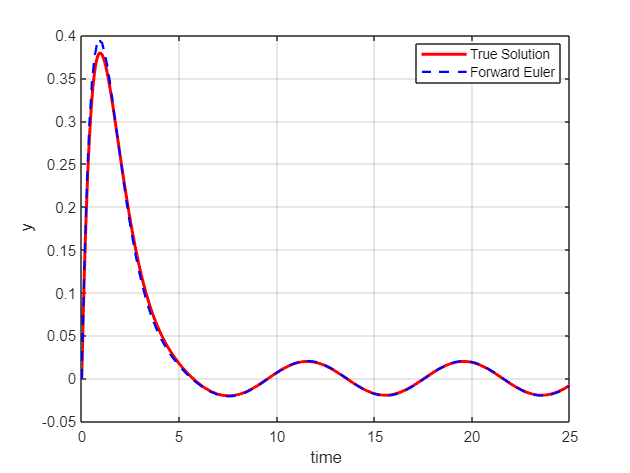

clear all
dT = 0.065; %sec
T = 0:dT:25; 

%-----------------------------------------------------------------------------
% write the your code here.

% Initial Condition
I = eye(3);
M = [0 1 0; 0 0 1; -37.5 -61.25 -32];
x = eye(3);
x(:, 1) =[0; 1; 0]; 

for n = 1:length(T)-1
    x(:,n+1) = x(:, n) + dT*(M*x(:, n) + [0; 0; sin(pi*T(n)/4)]);
end

%------------------------------------------------------------------------------
load('q1_refSol.mat') % load true analytical sol for reference.

figure()
plot(Q1_Tref,Q1_ref_sol,'r-','LineWidth',2,'displayname','True Solution') % plots true solution for comparison
hold on 
%-------------------------------------------------------------------------------


% plot your solution here.
plot(T, x(1, :),'b--','LineWidth',1.5,'displayname','Forward Euler')
% Note: the variable y is the y(t).  You may choose to rename it according
% to your preference,.                                        
%--------------------------------------------------------------------------------                                                              
                                                              
xlabel('time')
ylabel('y')
grid on
legend("Location","best")

g. Run the code you wrote in part f again, run the code for $25s$ and use the time step $\Delta t= 0.068s$.  Plot  $y(t)$ vs $t$ on the same plot as the true solution.

*Note: You may copy the code you wrote in part f in the cell below to run it for *$\Delta t =0.068s$ 

Comment on the solutions obtained in part e and f. **(2 marks)**

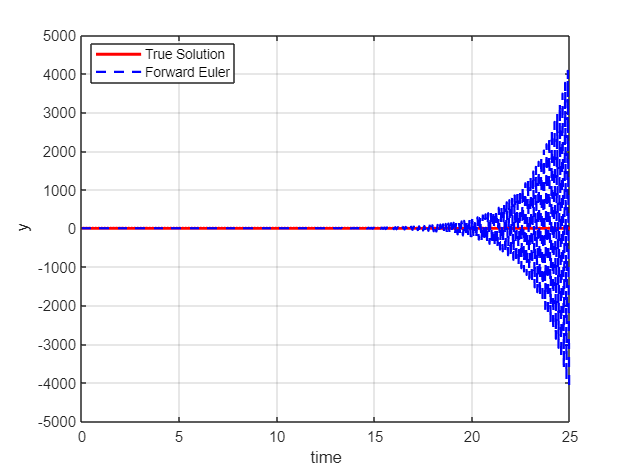

clear all
dT = 0.068; %sec
T = 0:dT:25; 

%-----------------------------------------------------------------------------
% write the your code here.

% Initial Condition
I = eye(3);
M = [0 1 0; 0 0 1; -37.5 -61.25 -32];
x = eye(3);
x(:, 1) =[0; 1; 0]; 

for n = 1:length(T)-1
    x(:,n+1) = x(:, n) + dT*(M*x(:, n) + [0; 0; sin(pi*T(n)/4)]);
end

%------------------------------------------------------------------------------
load('q1_refSol.mat') % load true analytical sol for reference.

figure()
plot(Q1_Tref,Q1_ref_sol,'r-','LineWidth',2,'displayname','True Solution') % plots true solution for comparison
hold on 
%-------------------------------------------------------------------------------


% plot your solution here.
plot(T, x(1, :),'b--','LineWidth',1.5,'displayname','Forward Euler')
% Note: the variable y is the y(t).  You may choose to rename it according
% to your preference,.                                        
%--------------------------------------------------------------------------------                                                              
                                                              
xlabel('time')
ylabel('y')
grid on
legend("Location","best")

*% you can type  your comments  here.*

Forward Euler is not always stable. It is only stable for some value of step size (small step size). The solution remain stable in f but not g. The step value for g is too big. Therefore, g is not accurate and f is way more accurate. 

h. In the  lecture, we discussed how the poles of a first-order system of ODE equations can be used to determine the step size for which the Forward Euler is stable. Using the poles of the system you obtained in part a, find the largest step size, $\Delta t$, for which the Forward Euler method is stable. Show all your equations. **(6 marks)**

*% you can type  your solution here.*

Eigenvalues: 


$$\begin{array}{l}
\lambda_1 =-30\\
\lambda_2 =-1+i\frac{1}{2}\\
\lambda_3 =-1-i\frac{1}{2}
\end{array}$$


For Complex poles 


$${\left|1+x+\textrm{jy}\right|}^2 <1$$



$$\begin{array}{l}
{\left(x+1\right)}^2 +y^2 <1\\
\frac{1}{4}<1
\end{array}$$


Therefore, the two complex poles are stable. 


$$\begin{array}{l}
\left|1+\Delta t\lambda \right|<1\\
-2<\Delta t\lambda <0
\end{array}$$


$-2<$-30$\Delta t$    -30$\Delta t$ < 0

$\Delta t$ < 1/15         $\Delta t$ >0 

Therefore 0 < $\Delta t$ < 1/15

The largest step size is 1/15 which is around 0.067. 